# Price the Put Options Contained in the Instrument Set

Load the EQP tree and instruments from the data file `deriv.mat`. Price the put options contained in the instrument set.  

load deriv.mat; 
EQPSubSet = instselect(EQPInstSet, 'FieldName', 'OptSpec', ...
'Data', 'put')

instdisp(EQPSubSet)

Price the put options.

[Price, PriceTree] = eqpprice(EQPTree, EQPSubSet)

You can use [treeviewer](docid:fininst_ug.btxewwl-1878) to see the prices of these three instruments along the price tree.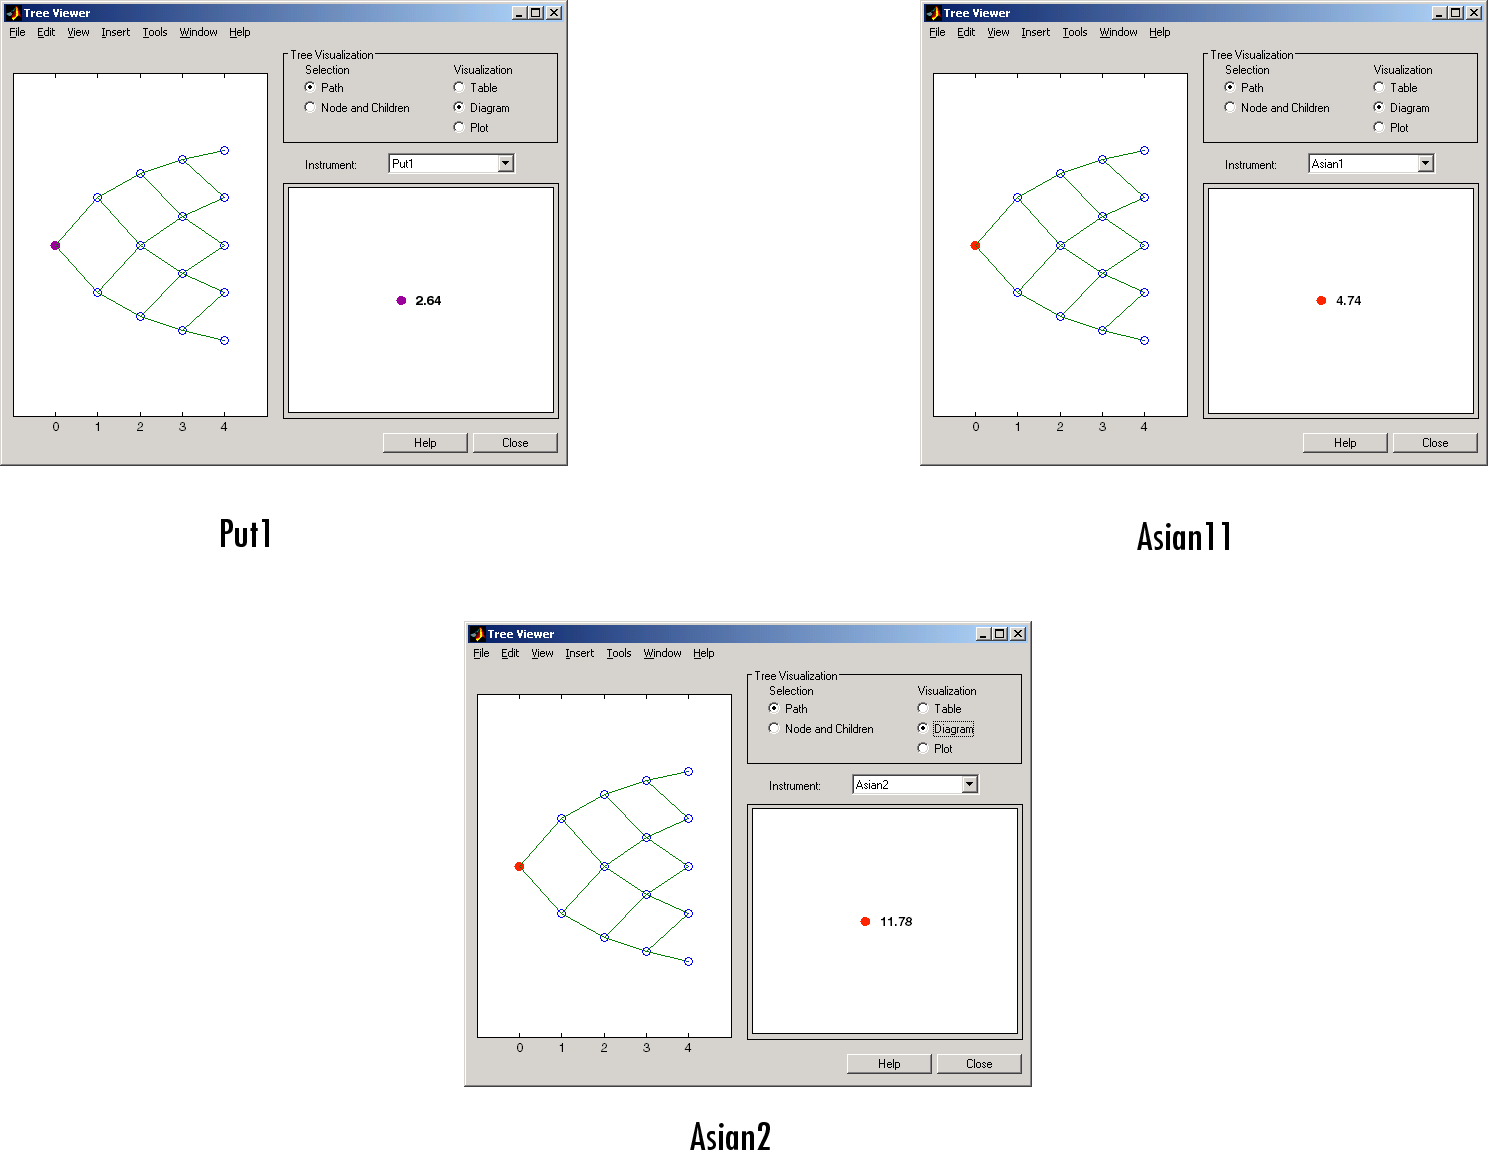

*Copyright 2018 The MathWorks, Inc.*